clear
p=2;
n=10;
m=100000;
nu=n-1;

mu_h=67;sig_h=2;
mu_w=150;sig_w=4;
rho=0.75;
S=[sig_h*sig_h rho*sig_h*sig_w;
   rho*sig_h*sig_w sig_w*sig_w];
A=chol(S)';

U1=rand(n,1);
U2=rand(n,1);
Z1=sqrt(-2.*log(U1)).*cos(2*pi.*U2);
Z2=sqrt(-2.*log(U1)).*sin(2*pi.*U2);
X1 = A(1,1)*Z1+mu_h;
X2 = A(2,1)*Z1+A(2,2)*Z2+mu_w;
X=[X1';X2'] 

X =    67.7022   67.8746   70.9169   66.1522   67.5949   69.7109   64.1808   68.8965   67.1545   67.5175
  152.4695  151.0956  154.4462  148.8317  148.4847  158.5076  147.7680  151.3766  149.4793  150.5982



%x bar_1
X_bar=[mean(X1);mean(X2)]

X_bar =    67.7701
  151.3057



%G_1
G=(X-repmat(X_bar,1,10))*(X-repmat(X_bar,1,10))'

G =    30.9280   42.3370
   42.3370   93.5635



% for j=1:m
%     U1=rand(n,1);
%     U2=rand(n,1);
%     Z1A=sqrt(-2.*log(U1)).*cos(2*pi.*U2);
%     Z2A=sqrt(-2.*log(U1)).*sin(2*pi.*U2);
%     X1 = A(1,1)*Z1A+mu_h;
%     X2 = A(2,1)*Z1A+A(2,2)*Z2A+mu_w;
%     X=[X1';X2'];
% 
%     Xbari(:,j)=[mean(X1);mean(X2)];
%     Gi(:,:,j)=(X-repmat(X_bar,1,10))*(X-repmat(X_bar,1,10))';
% end
k=n*m;
U1k=rand(k,1);
U2k=rand(k,1);
Z1k=sqrt(-2.*log(U1k)).*cos(2*pi.*U2k);
Z2k=sqrt(-2.*log(U1k)).*sin(2*pi.*U2k);
Xf=[Z1k';Z2k']

Xf =    -0.7535   -2.0101    0.3457   -0.2876    0.1942   -0.7443   -0.7000    0.4831   -0.9081    1.6409   -0.6086   -2.5986    1.5998    1.1845   -2.1595   -0.0353    0.1151   -1.2015    0.0629   -1.5075    1.0650   -0.7110    0.6180   -0.6279    0.1427   -0.9479    1.0822   -0.0884   -0.7634   -0.3783    0.7228   -0.7363    0.4075    1.6832   -0.3511   -0.7143    0.2806   -1.4483    0.6342    1.1914    0.7343    1.1997    0.2254   -0.8458    0.3781   -0.2580    0.0786    1.1500    1.9473    0.5983
    0.5255   -1.6199    0.4556    0.2321    0.8587   -0.0292    0.3222   -1.2800    0.1422   -0.9151    0.5708    0.3763   -0.0923    2.1789    0.0030   -0.6223   -0.8455    0.9238   -0.3133    2.1129    0.7166    1.1923    0.3905    0.2532    1.8260   -0.7275   -0.6676   -0.9301    0.3224    0.6479    1.4325    0.4796    0.8246    0.8942   -2.0332    0.9395   -0.0588   -0.2405    0.8181    1.2548    0.1812   -1.1370    1.1453    0.0239    0.2968   -0.1287   -1.0953    1.6215    0.1080    


XX=A*Xf+repmat([mu_h;mu_w],[1,n*m]);
X=zeros(p,n,m);
for j=1:m
    X(:,:,j)=XX(:,(j-1)*n+1:n*j);
end

Meanx=squeeze(mean(X,2))

Meanx =    66.4521   65.9703   66.8782   67.3339   68.0416   67.4865   66.4276   66.6133   66.5267   67.5496   68.1043   66.4380   67.7280   66.7083   66.9303   65.6656   67.0814   66.8736   67.3449   66.5955   66.3250   66.4074   67.2784   67.0555   67.9435   67.1553   65.5960   67.5775   66.7388   66.6599   66.6790   66.5229   66.6730   67.7650   66.4888   67.9725   67.6849   67.6958   67.6560   67.2505   67.7172   67.1645   66.3857   68.1339   66.6035   66.8300   66.3888   66.4826   67.3266   66.6858
  148.8321  149.5910  150.6173  151.6414  152.2372  151.5395  148.2969  149.9374  149.2322  150.4160  152.6262  148.8795  151.2252  150.3573  151.5979  147.6226  150.5140  150.1792  150.6108  149.2704  149.8184  150.0481  148.1566  149.8197  150.8476  150.6269  148.4310  149.4635  149.8281  149.8703  148.7379  148.9300  150.8916  150.8110  149.8945  152.3241  149.2538  150.9114  152.0253  151.1025  149.5026  148.6527  147.4436  150.6192  149.1715  149.7357  148.8308  149.3832  150.2371 

covX=zeros(p,p,m);

for j = 1:m
    covX(:,:,j)=cov(squeeze(X(:,:,j)'));
end

Gi=(n-1)*covX

Gi = Gi(:,:,1) =

   35.5686   54.9746
   54.9746  129.1951


Gi(:,:,2) =

   67.3320   95.2901
   95.2901  203.6682


Gi(:,:,3) =

   20.8092   31.2171
   31.2171   95.3782


Gi(:,:,4) =

   33.6659   72.6815
   72.6815  206.8713


Gi(:,:,5) =

   22.8829   38.1937
   38.1937  121.1128


Gi(:,:,6) =

   24.7191   48.4952
   48.4952  155.2606


Gi(:,:,7) =

   14.8012   19.7425
   19.7425   68.3066


Gi(:,:,8) =

   44.2548   59.4001
   59.4001  210.5004


Gi(:,:,9) =

   28.3275   63.1646
   63.1646  192.3812


Gi(:,:,10) =

   36.6436   53.1372
   53.1372  158.4940


Gi(:,:,11) =

   56.0389   50.1588
   50.1588   80.4879


Gi(:,:,12) =

   60.7369  110.1504
  110.1504  236.7192


Gi(:,:,13) =

   33.1843   27.5935
   27.5935  115.2839


Gi(:,:,14) =

   20.7881    9.3853
    9.3853   75.0385


Gi(:,:,15) =

   44.5563   82.4143
   82.4143  198.9284


Gi(:,:,16) =

   28.5599   16.0132
   16.0132   93.8548


Gi(:,:,17) =

   15.6629   22.8566
   22.8566  145.3747


Gi(:,:,18) =

   2

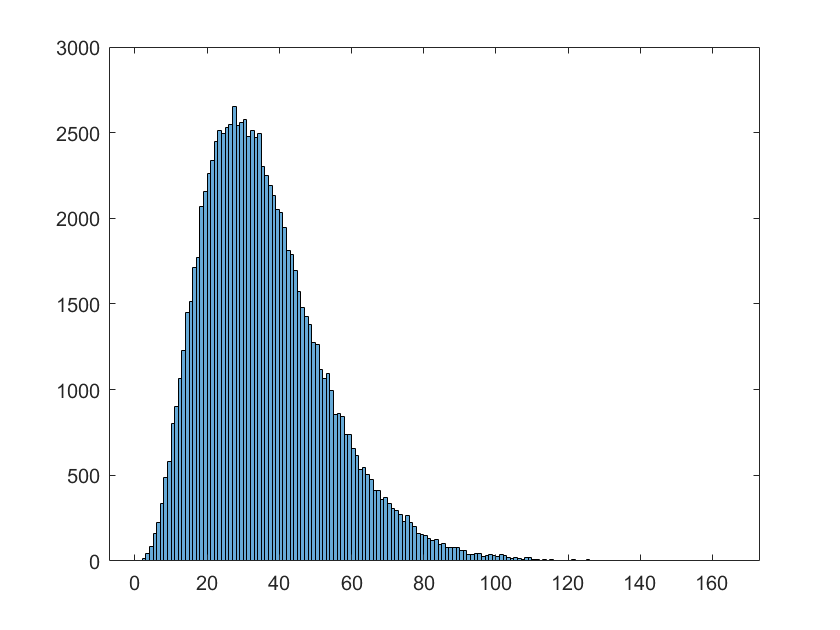


histogram(Gi(1,1,:))

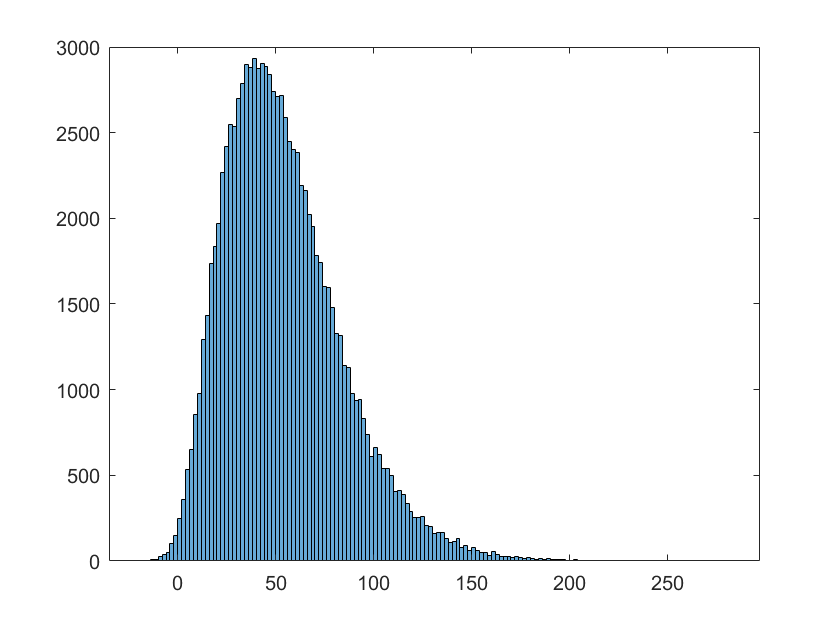

histogram(Gi(1,2,:))

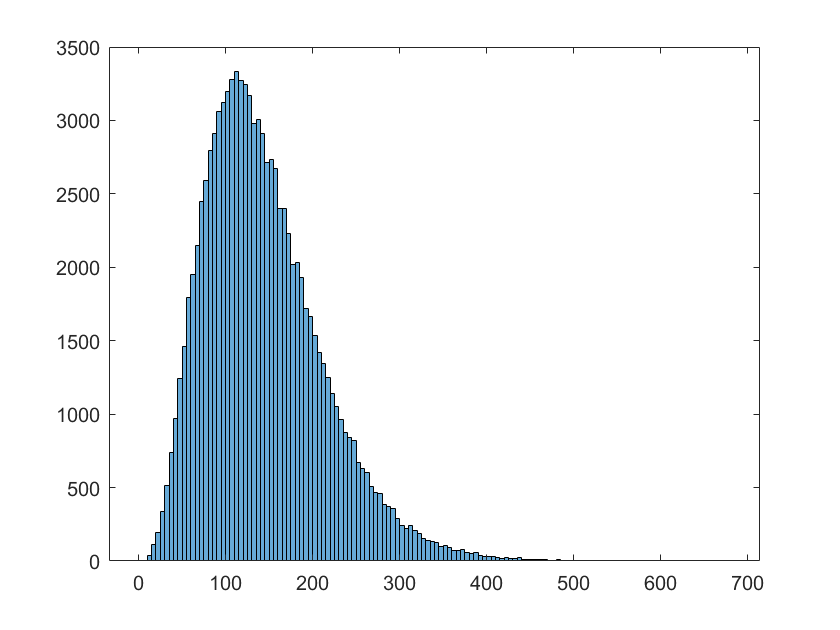

histogram(Gi(2,2,:))


%mean
Mean_Gi=[mean(reshape(Gi(1,1,:),m,1)) mean(reshape(Gi(1,2,:),m,1));
    mean(reshape(Gi(2,1,:),m,1)) mean(reshape(Gi(2,2,:),m,1))]

Mean_Gi =    35.9834   54.0225
   54.0225  144.0060



Th_Mean=nu*S

Th_Mean =     36    54
    54   144



%var
Var_Gi=var(Gi,[],3)

Var_Gi = 	1.0e+03 *

    0.2880    0.9001
    0.9001    4.6108



Th_var=zeros(p,p);
for j=1:p
    for k=1:p
        Th_var(j,k)=nu*(S(j,k)^2+S(j,j)*S(k,k));
    end
end
Th_var

Th_var =          288         900
         900        4608



%cov
covG1112=cov(squeeze(Gi(1,1,:)),squeeze(Gi(1,2,:)));
covG1122=cov(squeeze(Gi(1,1,:)),squeeze(Gi(2,2,:)));
covG1222=cov(squeeze(Gi(1,2,:)),squeeze(Gi(2,2,:)));
Cov_G=[covG1112(1,2),covG1122(1,2),covG1222(1,2)]

Cov_G = 	1.0e+03 *

    0.4317    0.6455    1.7287



i=1;j=1;k=1;l=2;
cG1112=nu*(S(i,k)*S(j,l)+S(i,l)*S(j,k));
i=1;j=1;k=2;l=2;
cG1122=nu*(S(i,k)*S(j,l)+S(i,l)*S(j,k));
i=1;j=2;k=2;l=2;
cG1222=nu*(S(i,k)*S(j,l)+S(i,l)*S(j,k));
Th_cov=[cG1112,cG1122,cG1222]

Th_cov =          432         648        1728
